# Sensing System - revA

Changes since previous version:

- implemented capability to compute the chirp rate

- allowed for chirps with different cycle periods to be implemented for testing purposes

## Assumptions/Settings

Chirp Parameters:

- cycle period: 50 us

- idle time: 30 us

- slope: 1 MHz/us

- BW: 20 MHz

- SDR sampling rate: 50 Msps

"Spectogram Settings"

- fft size: 32 bin

- frequency sampling period: 1us (sampled every us)

## Constructing the Chirp

%configure chirp parameters
chirp_params.cycle_period_us = 25;
chirp_params.slope_MHz_us = 1.20;
chirp_params.BW_MHz = 20;                   %the bandwidth will be close to this but may not be exactly this
chirp_params.FMCW_sample_rate_Msps = 50;
chirp_params.ramp_end_time_us = ceil(chirp_params.BW_MHz / chirp_params.slope_MHz_us);
chirp_params.BW_MHz = chirp_params.ramp_end_time_us * chirp_params.slope_MHz_us;
chirp_params.idle_time_us = chirp_params.cycle_period_us - chirp_params.ramp_end_time_us;
chirp_params.num_samples_idle_time = int32(chirp_params.idle_time_us * chirp_params.FMCW_sample_rate_Msps);

%configure frame parameters
frame_params.num_chirps = 32;

%configure waveform parameters
waveform_params.sample_rate_Hz = chirp_params.FMCW_sample_rate_Msps * 1e6;
waveform_params.sweep_time_s = chirp_params.ramp_end_time_us * 1e-6;
waveform_params.sweep_BW_Hz = chirp_params.BW_MHz * 1e6;
waveform_params.sweep_interval = 'Positive';
waveform_params.sweep_direction = 'Up';
waveform_params.output_format = 'Sweeps';
waveform_params.num_sweeps = 1;

waveform = phased.FMCWWaveform("SampleRate",waveform_params.sample_rate_Hz, ...
                                'SweepTime', waveform_params.sweep_time_s, ...
                                'SweepBandwidth', waveform_params.sweep_BW_Hz, ...
                                'SweepDirection', waveform_params.sweep_direction, ...
                                'SweepInterval', waveform_params.sweep_interval, ...
                                'OutputFormat',waveform_params.output_format, ...
                                'NumSweeps',waveform_params.num_sweeps);

chirp = [zeros(chirp_params.num_samples_idle_time,1); waveform()];

## Generate a Spectogram

Steps to generate spectoram:

- reshape into 1us wide windows to sample frequency at (ex: 50 samples per 1us when sampling at 50 Msps)

- reduce the number of samples in the window to the desired size of fft (ex: 32 bits)

- window the sample signal

- perform fft

#### Initialize Spectogram Parameters

spectogram_params.fft_size = 32;
%for use in the simulink model
fft_size = spectogram_params.fft_size;
spectogram_params.freq_sampling_period_us = 1; %sample frequency every 1us
spectogram_params.num_samples_per_sampling_window = spectogram_params.freq_sampling_period_us * chirp_params.FMCW_sample_rate_Msps;
spectogram_params.num_freq_spectrum_samples_per_spectogram = 50;
spectogram_params.num_ADC_samples_per_spectogram = spectogram_params.num_freq_spectrum_samples_per_spectogram * spectogram_params.num_samples_per_sampling_window;

%compute the window to be used when generating the spectogram
window = hann(spectogram_params.fft_size);


#### Compute Spectogram for specified number of chirps

%initialize array to track captured chirps
chirps_to_capture = 128;        %this will be the maximum number of chirps captured when computing the average chirp duration
num_captured_chirps = 0;
captured_chirps = zeros(chirps_to_capture, 2);
average_chirp_duration = 20;
average_slope = 0;

%initialize array to hold the previously measured spectrum
previous_spectogram_points = [];

%initialize counter to keep track of how many full iterations of the while loop
%have occurred
while_loop_count = 0;

%first compute the sampled chirp that the sensing system would receive

%create additional counting variables to aid in the construction of the
%received chirp
chirp_sample_index = 1;
max_chirp_sample_index = size(chirp,1);
chirp_samples_left = max_chirp_sample_index - 1;
 
received_sample_index = 1;
max_received_sample_index = spectogram_params.num_ADC_samples_per_spectogram;
received_samples_left = max_received_sample_index - 1;

num_chirps_to_compute = frame_params.num_chirps;
chirp_count = 0;
while chirp_count < num_chirps_to_compute

    received_signal = zeros(spectogram_params.num_ADC_samples_per_spectogram,1);
    received_signal_assembled = 0;

    while ~received_signal_assembled
        if chirp_count >= num_chirps_to_compute
            %if this is the last chirp in the frame, fill in the remaining
            % part of the received signal with zeros
            points_to_insert = received_samples_left;
            
            received_signal(received_sample_index:received_sample_index + points_to_insert) = zeros(points_to_insert + 1,1);
            
            received_sample_index = 1;
            received_samples_left = max_received_sample_index - 1;
            received_signal_assembled = 1;
        elseif received_samples_left >= chirp_samples_left
            points_to_insert = chirp_samples_left;
            received_signal(received_sample_index:received_sample_index + points_to_insert) = chirp(chirp_sample_index:chirp_sample_index + points_to_insert);
            
            chirp_sample_index = 1;
            chirp_samples_left = max_chirp_sample_index - 1;
            chirp_count = chirp_count + 1;
        
            received_sample_index = received_sample_index + points_to_insert + 1;
            received_samples_left = max_received_sample_index - received_sample_index;

            if received_samples_left < 0
                received_sample_index = 1;
                received_samples_left = max_received_sample_index - 1;
                received_signal_assembled = 1;
            end
            
        else
            points_to_insert = received_samples_left;
            received_signal(received_sample_index:received_sample_index + points_to_insert) = chirp(chirp_sample_index:chirp_sample_index + points_to_insert);
        
            chirp_sample_index = chirp_sample_index + points_to_insert + 1;
            chirp_samples_left = max_chirp_sample_index - chirp_sample_index;
        
            received_sample_index = 1;
            received_samples_left = max_received_sample_index - 1;
            received_signal_assembled = 1;
        end
    end

    reshaped_signal = reshape(received_signal,spectogram_params.num_freq_spectrum_samples_per_spectogram,[]);
    
    %next, shave off the last few samples so that we get the desired fft size
    reshaped_signal_for_fft = reshaped_signal(1:spectogram_params.fft_size,:);
    
    %window the signal
    windowed_signal = reshaped_signal_for_fft .* window;
    
    %perform an fft
    generated_spectogram = fft(windowed_signal);
    
    %clip off the negative frequencies;
    generated_spectogram = generated_spectogram(1:spectogram_params.fft_size/2,:);
    half_fft_size = spectogram_params.fft_size/2;
    
    %plot the spectogram to confirm correct implementation
    plot_params.max_freq = chirp_params.FMCW_sample_rate_Msps/2;
    plot_params.freq_resolution = chirp_params.FMCW_sample_rate_Msps/spectogram_params.fft_size;
    plot_params.frequencies = 0:plot_params.freq_resolution:plot_params.max_freq - plot_params.freq_resolution;
    plot_params.times = 0: spectogram_params.freq_sampling_period_us : spectogram_params.num_freq_spectrum_samples_per_spectogram - spectogram_params.freq_sampling_period_us;
    
%     imagesc(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
%     subplot(3,1,1);
%     surf(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
%     title_str = sprintf('Spectogram');
%     title(title_str);
%     xlabel('Time(us)')
%     ylabel('Frequency (MHz)')
%     view([0,90.0])

## Detect Peaks in the Spectogram

    peak_detection_params.threshold = 5;
    peak_detection_params.numPeaks = 2;
    spectogram_points = [];  %array to hold the time, freq locations of valid spectogram points
    

    for i = 1:size(generated_spectogram,2)
        [peaks,locations] = findpeaks(abs(generated_spectogram(:,i)),"NPeaks",peak_detection_params.numPeaks);
        locations = locations(peaks > peak_detection_params.threshold);
        if ~isempty(locations)
            locations = [locations.'; i * ones(1,size(locations,1))];
            spectogram_points = [spectogram_points,locations];
        end
    end
    
    %perform clustering on the new spectogram combined with the previous
    %one

Reshaped Signal: 		 Matches

    if ~isempty(spectogram_points)
        combined_spectogram = [previous_spectogram_points,spectogram_points + [0;spectogram_params.num_freq_spectrum_samples_per_spectogram]];
    else
        combined_spectogram = previous_spectogram_points;
    end
    previous_spectogram_points = spectogram_points;
    [idx,corepts] = dbscan((combined_spectogram).',5,2);
    
    %compute new times for the combined_spectogram
    plot_params.combined_spectogram_times = 0: spectogram_params.freq_sampling_period_us : 2 * spectogram_params.num_freq_spectrum_samples_per_spectogram - spectogram_params.freq_sampling_period_us;

Reshaped Signal for fft: 	 Matches


    %plot the detected points to confirm that they align
    detected_frequencies = plot_params.frequencies(combined_spectogram(1,:));
    detected_times = plot_params.combined_spectogram_times(combined_spectogram(2,:));
%     subplot(3,1,2);
%     gscatter(detected_times,detected_frequencies,idx);

Windowed Signal: 	 Matches

## Fit a linear model to the computed points to determine slope and intercept

#### Initial Linear Model Computation

 - removed for more practical implementation

#### Revised Linear Model Computation:

link to resourse used to compute linear model: [https://online.stat.psu.edu/stat462/node/132/](https://online.stat.psu.edu/stat462/node/132/) 

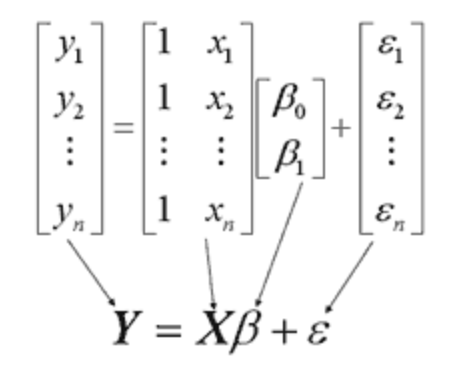

solving for this with out the Epsilon term though


$$\beta = (X^{T}X)^{-1}X^{T}Y$$


    %solve for the linear equation for each cluster provided there are enough
    %points
    max_num_clusters = 10;
    threshold = 15;
    detected_chirps = zeros(max(idx),2);
    for cluster_id = 1:max(idx)
        %solve for linear model using linear algrebra
        %y is frequencies, x is time
        if sum(idx == cluster_id) > threshold

Generated Spectogram: 	 Matches

            X = [ones(size(detected_times(idx == cluster_id),2),1),detected_times(idx == cluster_id).'];
            Y = detected_frequencies(idx == cluster_id).';
            B = inv(X.' * X) * X.' * Y;
            detected_chirps(cluster_id,1:2) = [-B(1)/B(2),B(2)];
            slope = detected_chirps(cluster_id,2);
            intercept = detected_chirps(cluster_id,1);
        end
    end

#### Simplified Linear Model

In order to implement this on physical hardware, I also wanted to experiment with implementing using the same number of points and to see how this affects the accuracy

    %Now, we experiment with only taking 15 points to determine the slope and
    %intercept
    num_points_for_linearizing = 15;
    detected_chirps_simplified = zeros(max(idx),2);
    for cluster_id = 1:max(idx)
        if sum(idx == cluster_id) >= num_points_for_linearizing
            cluster_times = detected_times(idx == cluster_id);

            cluster_freqs = detected_frequencies(idx == cluster_id);
            X_simplified = [ones(num_points_for_linearizing,1),cluster_times(1:num_points_for_linearizing).'];
            Y_simplified = cluster_freqs(1:num_points_for_linearizing).';
            B_simplified = inv(X_simplified.' * X_simplified) * X_simplified.' * Y_simplified;
            detected_chirps_simplified(cluster_id,1:2) = [-B_simplified(1)/B_simplified(2),B_simplified(2)];
            slope_simplified = detected_chirps_simplified(cluster_id,2);
            intercept_simplified = detected_chirps_simplified(cluster_id,1);
        end
    end
    %detected_chirps_simplified - detected_chirps;
    %shows that decreasing the number of points affected the computed intercept
    %point

### Compute the average chirp period and average slope

    detected_chirps = detected_chirps + [spectogram_params.num_freq_spectrum_samples_per_spectogram * (while_loop_count - 1), 0];
    for i = 1:size(detected_chirps,1)

        if detected_chirps(i,2) ~= 0 && num_captured_chirps < chirps_to_capture
            if num_captured_chirps == 0
                captured_chirps(1,:) = detected_chirps(i,:);
                num_captured_chirps = num_captured_chirps + 1;
            elseif all(abs(captured_chirps - detected_chirps(i,1)) > average_chirp_duration / 2,'all')
                captured_chirps(num_captured_chirps + 1,:) = detected_chirps(i,:);
                num_captured_chirps = num_captured_chirps + 1;

Detected Times: 	 Matches

            end
            average_slope = sum(captured_chirps(1:num_captured_chirps,2))/ double(num_captured_chirps);
            if num_captured_chirps >= 2
                average_chirp_duration = (captured_chirps(num_captured_chirps,1) - captured_chirps(1,1))/double(num_captured_chirps - 1);
            end
            
        end

Detected Frequencies: 	 Matches

    end

    while_loop_count = while_loop_count + 1;
end

## Check simulated values to make sure that they are the same as matlab computed values

### Initialize the Simulink model and run it

open_system('SensingSubsystem_revA');
stop_time = while_loop_count * spectogram_params.num_ADC_samples_per_spectogram / waveform_params.sample_rate_Hz;
set_param('SensingSubsystem_revA','StopTime','stop_time');
out = sim('SensingSubsystem_revA','SimulationMode','normal','SaveOutput','on');

Detected Chirps: 	 Matches

### Reshaped Signal

%check a few chirps later to ensure that no timing errors or drift
reshaped_signal_simulink = out.reshaped_signal(:,:,2);
compare = all(reshaped_signal == reshaped_signal_simulink,'all');

if compare
    fprintf("Reshaped Signal: \t\t Matches")
else
    fprintf("Reshaped Signal: \t\t Does Not Match")
end

Captured Chirps: 	 Matches

### Reshaped Signal - for fft

reshaped_signal_for_fft_simulink = out.reshaped_signal_for_fft(:,:,2);
compare = all(reshaped_signal_for_fft == reshaped_signal_for_fft_simulink,'all');

if compare
    fprintf("Reshaped Signal for fft: \t Matches")
else

Num Captured Chirps: 	 Matches

    fprintf("Reshaped Signal for fft: \t Does Not Match")
end

Average Slope: 	 Matches

### Windowed Signal

windowed_signal_simulink = out.windowed_signal(:,:,2);
compare = all(windowed_signal == windowed_signal_simulink);
if compare
    fprintf("Windowed Signal: \t Matches")
else
    fprintf("Windowed Signal: \t Does Not Match")

Average Chirp Duration: 	 Matches

end

### Generated Spectogram

generated_spectogram_simulink = out.generated_spectogram(:,:,2);

average_slope = 1.2017

compare = all(generated_spectogram == generated_spectogram_simulink);

average_chirp_duration = 25

if compare
    fprintf("Generated Spectogram: \t Matches")
else
    fprintf("Generated Spectogram: \t Does Not Match")
end
%imagesc(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
subplot(2,1,1)
surf(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
title_str = sprintf('Spectogram - From Script');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])
subplot(2,1,2)
surf(plot_params.times,plot_params.frequencies, abs(generated_spectogram_simulink));
title_str = sprintf('Spectogram - From Simulink');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])

### Detect Peaks

%obtain the detected times and frequencies
detected_times_simulink = out.detected_times(2,:);
detected_frequencies_simulink = out.detected_frequencies(2,:);
idx_simulink = out.idx(:,:,2);


subplot(2,1,1);
gscatter(detected_times,detected_frequencies,idx);
title('From Matlab Script')
subplot(2,1,2);
gscatter(detected_times_simulink,detected_frequencies_simulink,idx_simulink);
title('From Simulink')
%compare detected chirps and output
compare = all(detected_times_simulink(detected_frequencies_simulink > 0) == detected_times); %frequencies won't be zero, time could be zero
if compare
    fprintf("Detected Times: \t Matches")
else
    fprintf("Detected Times: \t Does Not Match")
end

compare = all(detected_frequencies_simulink(detected_frequencies_simulink > 0) == detected_frequencies);
if compare
    fprintf("Detected Frequencies: \t Matches")
else
    fprintf("Detected Frequencies: \t Does Not Match")
end

### Verifing detected chirp observations

detected_chirps_simulink = out.detected_chirps(:,:,2);

compare = (detected_chirps_simulink(detected_chirps_simulink(:,2) ~=0, :) - detected_chirps(detected_chirps(:,2) ~=0, :)) < 1e-10;
if compare
    fprintf("Detected Chirps: \t Matches")
else
    fprintf("Detected Chirps: \t Does Not Match")
end

### Verifing the computed slope and duration

captured_chirps_simulink = out.captured_chirps(:,:,2);
num_captured_chirps_simulink = out.chirp_count(2);
average_slope_simulink = out.slope(2);
average_chirp_duration_simulink = out.duration(2);

compare = all(abs(captured_chirps_simulink - captured_chirps) < 1e-10);
if compare
    fprintf("Captured Chirps: \t Matches")
else
    fprintf("Captured Chirps: \t Does Not Match")
end
compare = (num_captured_chirps_simulink == num_captured_chirps);
if compare
    fprintf("Num Captured Chirps: \t Matches")
else
    fprintf("Num Captured Chirps: \t Does Not Match")
end
compare = (abs(average_slope_simulink - average_slope) < 1e-10);
if compare
    fprintf("Average Slope: \t Matches")
else
    fprintf("Average Slope: \t Does Not Match")
end

compare = (abs(average_chirp_duration_simulink - average_chirp_duration) < 1e-10);
if compare
    fprintf("Average Chirp Duration: \t Matches")
else
    fprintf("Average Chirp Duration: \t Does Not Match")
end

### Results of Simulation

%average slope
average_slope
average_chirp_duration